# Correlation-Distance map for all mice 

#### Plot pair-wise distance and correlation for all cells 

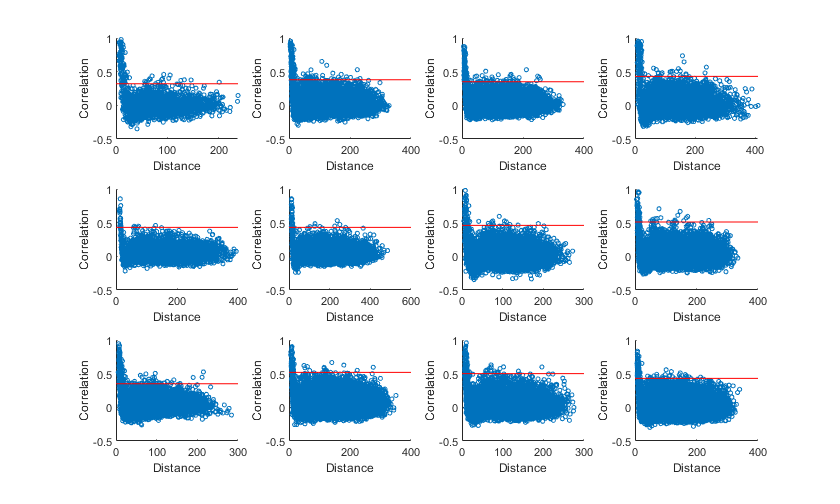

close all 
f=figure;f.Position(3)=1.5*f.Position(3);f.Position(4)=1.2*f.Position(4);
for p=1:6
   for m=1:2 % pair and mouse index 
ca=zscore(E{p}{m}.dFFCalciumTraces);
roi=E{p}{m}.ROIs;
[nf,nc]=size(ca);
cormat=corrcoef(ca);
cormat(1:length(cormat)+1:end)=0;cormat_v=squareform(cormat); % correlation matrix in the vector form 
distmat=pdist(roi);
subplot(3,4,2*(p-1)+m)
scatter(distmat,cormat_v,10);xlabel('Distance');ylabel('Correlation');ylim([-0.5 1])
th(p,m) = cor_threshold(cormat_v,distmat); % obtain threshold for correlation map 
line(xlim,[th(p,m) th(p,m)],'Color','r')
   end
end

# All 18 pairs remove contamination 

dis_th=40;

ans = 'Pair1,Mouse1,97(58%) cells removed'

ans = 'Pair1,Mouse2,40(20%) cells removed'

ans = 'Pair2,Mouse1,6(8.5%) cells removed'

ans = 'Pair2,Mouse2,40(39%) cells removed'

ans = 'Pair3,Mouse1,39(53%) cells removed'

ans = 'Pair3,Mouse2,90(36%) cells removed'

ans = 'Pair4,Mouse1,54(34%) cells removed'

ans = 'Pair4,Mouse2,129(55%) cells removed'

ans = 'Pair5,Mouse1,31(25%) cells removed'

ans = 'Pair5,Mouse2,100(38%) cells removed'

ans = 'Pair6,Mouse1,55(46%) cells removed'

ans = 'Pair6,Mouse2,98(41%) cells removed'

ans = 'Pair7,Mouse1,108(41%) cells removed'

ans = 'Pair7,Mouse2,65(44%) cells removed'

ans = 'Pair8,Mouse1,3(4.2%) cells removed'

ans = 'Pair8,Mouse2,58(36%) cells removed'

ans = 'Pair9,Mouse1,18(17%) cells removed'

ans = 'Pair9,Mouse2,32(17%) cells removed'

ans = 'Pair10,Mouse1,113(50%) cells removed'

ans = 'Pair10,Mouse2,86(54%) cells removed'

ans = 'Pair11,Mouse1,30(23%) cells removed'

ans = 'Pair11,Mouse2,69(47%) cells removed'

ans = 'Pair12,Mouse1,76(52%) cells removed'

ans = 'Pair12,Mouse2,61(40%) cells removed'

ans = 'Pair13,Mouse1,53(25%) cells removed'

ans = 'Pair13,Mouse2,59(25%) cells removed'

ans = 'Pair14,Mouse1,84(48%) cells removed'

ans = 'Pair14,Mouse2,51(22%) cells removed'

ans = 'Pair15,Mouse1,83(34%) cells removed'

ans = 'Pair15,Mouse2,89(38%) cells removed'

ans = 'Pair16,Mouse1,57(33%) cells removed'

ans = 'Pair16,Mouse2,87(32%) cells removed'

ans = 'Pair17,Mouse1,64(27%) cells removed'

ans = 'Pair17,Mouse2,84(30%) cells removed'

ans = 'Pair18,Mouse1,69(25%) cells removed'

ans = 'Pair18,Mouse2,72(27%) cells removed'

[remov]=remove_contamination(E,dis_th);

#### Distribution of degrees 

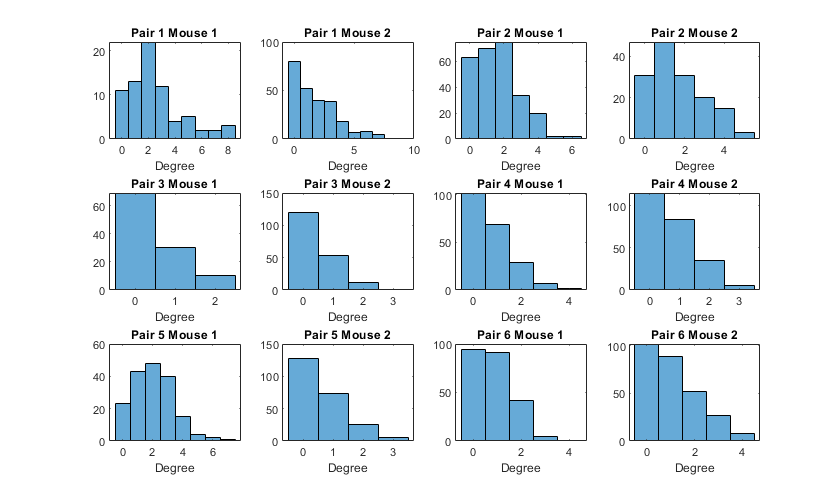

dis_th=40;
for p=1:6
   for m=1:2 
ca=zscore(E{p}{m}.dFFCalciumTraces);
roi=E{p}{m}.ROIs;
distmat=pdist(roi);
cormat=corrcoef(ca);
cormat(1:length(cormat)+1:end)=0;cormat(cormat<=th(p,m))=0;cormat(squareform(distmat)>dis_th)=0; 
degree=sum(cormat~=0);
subplot(3,4,2*(p-1)+m)
histogram(degree);xlabel('Degree');title(sprintf('Pair %d Mouse %d',p,m))
   end
end

#### Remove highly correlated closed-by cells 

% pick the highest degree and remove 
remov=cell(6,2);
for p=1:6
   for m=1:2 
ca=zscore(E{p}{m}.dFFCalciumTraces);
[~,nc]=size(ca);
roi=E{p}{m}.ROIs;
distmat=pdist(roi);
cormat=corrcoef(ca);
cormat(1:length(cormat)+1:end)=0;cormat(cormat<=th(p,m))=0;cormat(squareform(distmat)>dis_th)=0; 
deg=sum(cormat~=0);
remov{p,m}=[];indall=1:nc;
while sum(deg)>0
    [~,ind]=maxk(deg,1);
    remov{p,m}=[remov{p,m},indall(ind)];
    cormat(ind,:)=[];cormat(:,ind)=[];indall(ind)=[];
    deg=sum(cormat~=0);
end
% how many cells were removed?
sprintf('Pair%d,Mouse%d,%d(%.2g%%) cells removed',p,m,length(remov{p,m}),100*length(remov{p,m})/nc)
   end
end

ans = 'Pair1,Mouse1,39(53%) cells removed'

ans = 'Pair1,Mouse2,90(36%) cells removed'

ans = 'Pair2,Mouse1,108(41%) cells removed'

ans = 'Pair2,Mouse2,65(44%) cells removed'

ans = 'Pair3,Mouse1,18(17%) cells removed'

ans = 'Pair3,Mouse2,32(17%) cells removed'

ans = 'Pair4,Mouse1,53(25%) cells removed'

ans = 'Pair4,Mouse2,59(25%) cells removed'

ans = 'Pair5,Mouse1,84(48%) cells removed'

ans = 'Pair5,Mouse2,51(22%) cells removed'

ans = 'Pair6,Mouse1,64(27%) cells removed'

ans = 'Pair6,Mouse2,84(30%) cells removed'

#### Correlation map 

Plot closed-by correlated cells, with removed cells in orange and remaining cells in black.

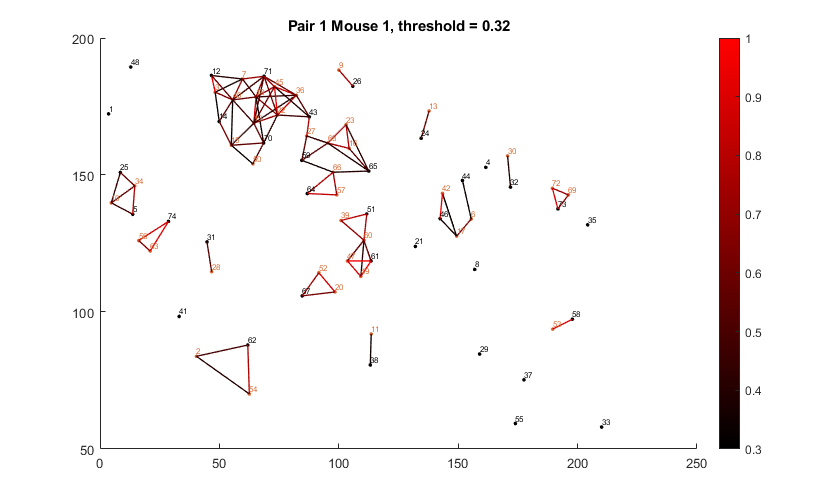

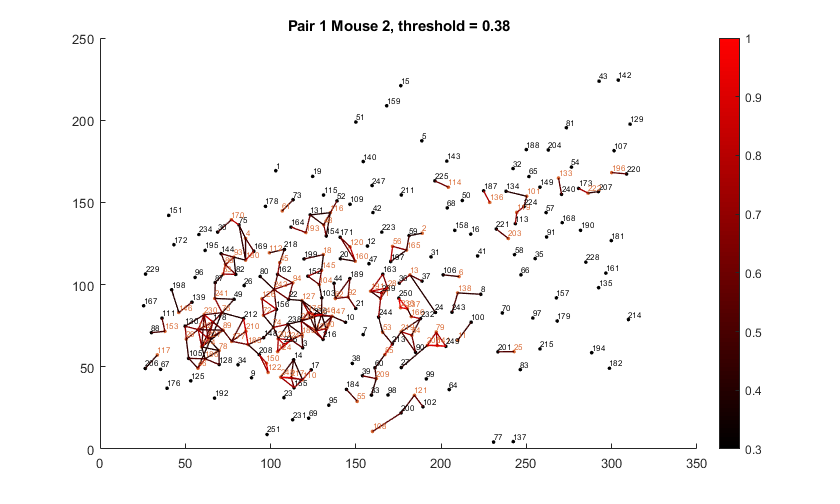

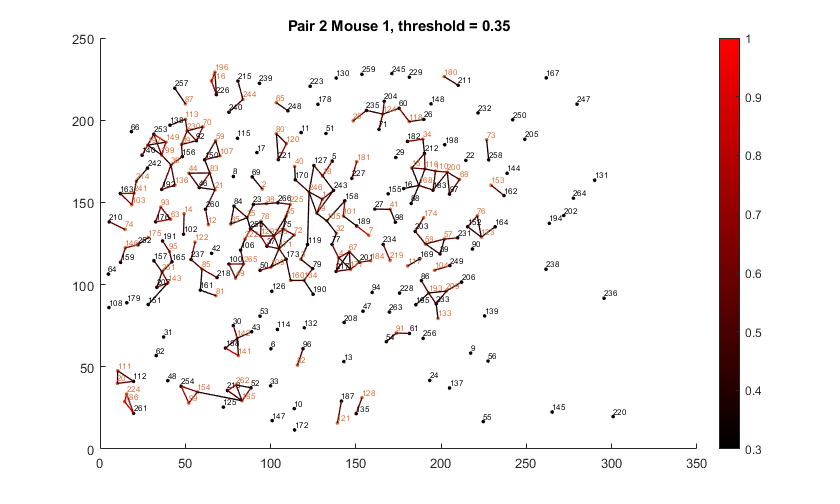

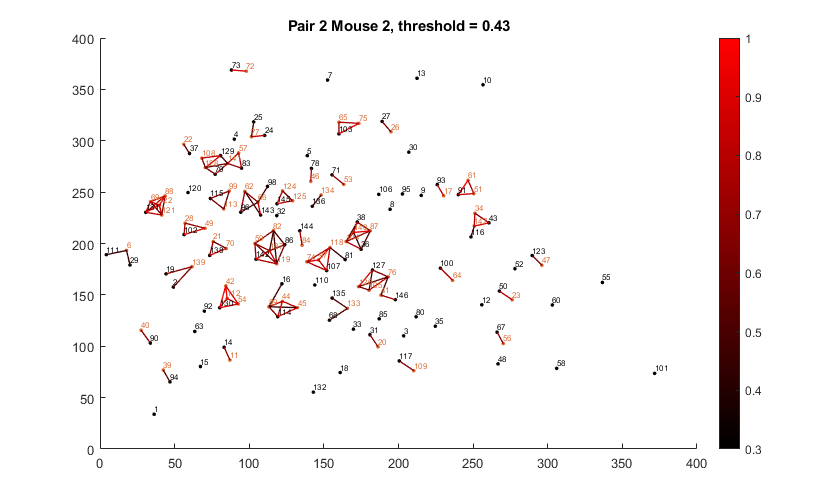

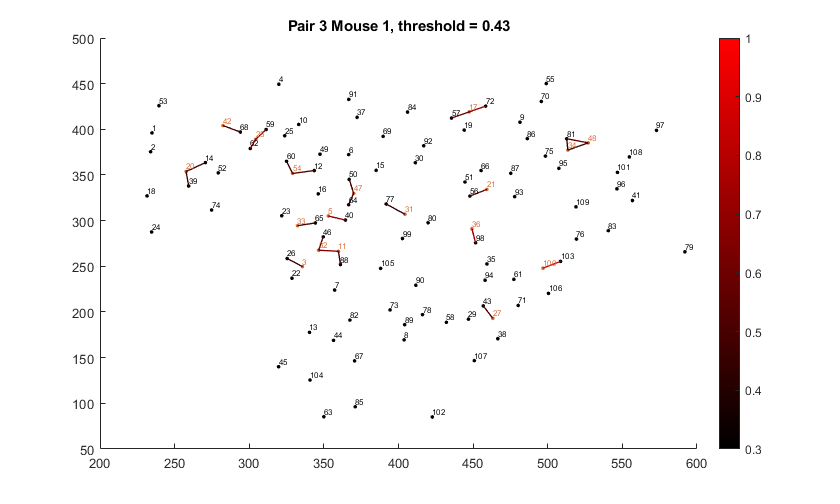

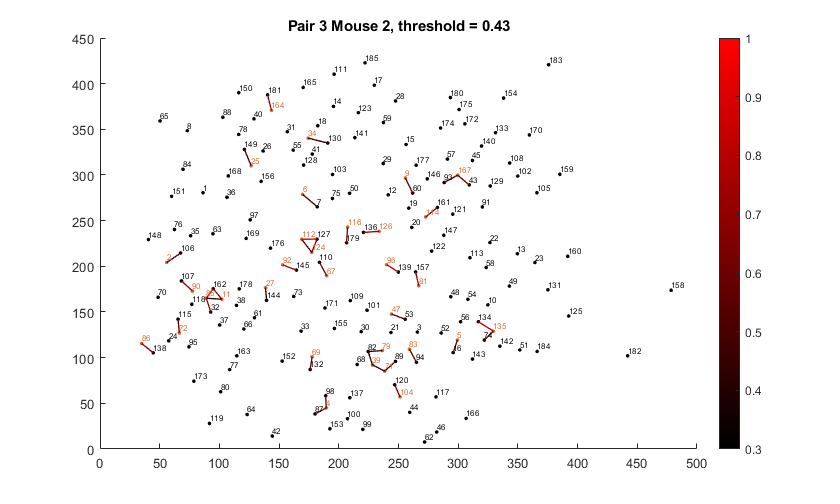

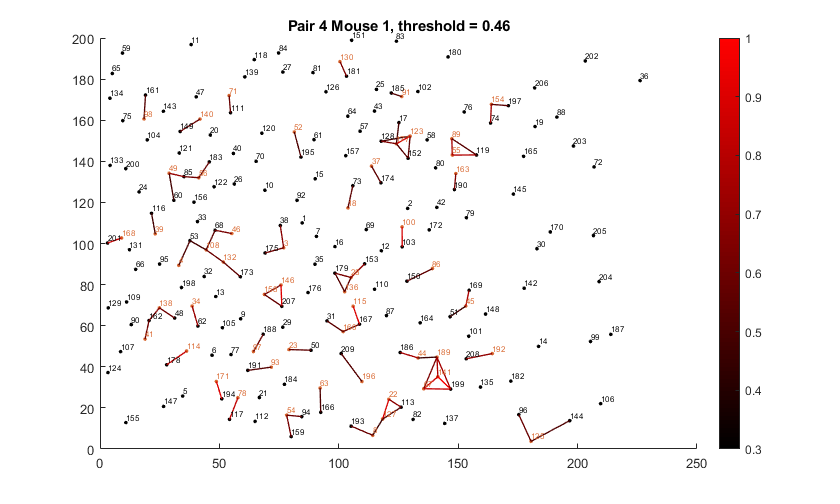

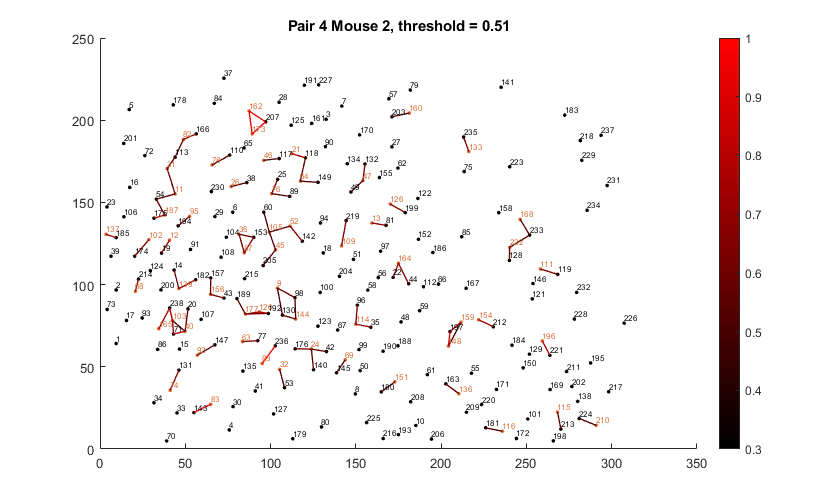

for p=1:6
for m=1:2
ca=zscore(E{p}{m}.dFFCalciumTraces);
[~,nc]=size(ca);
roi=E{p}{m}.ROIs;
cormat=corrcoef(ca); cormat(1:length(cormat)+1:end)=0;
distmat=pdist(roi);
cormat(cormat<=th(p,m))=0;cormat(squareform(distmat)>dis_th)=0; 
[r,c,v]=find(cormat);
% specify color of removed cells 
col_rem=repmat([0 0 0],nc,1);
col_rem(remov{p,m},:)=repmat([217 104 49]./255,length(remov{p,m}),1);
% 
f=figure;f.Position(3)=1.5*f.Position(3);f.Position(4)=1.2*f.Position(4);
scatter(roi(:,1),roi(:,2),8,col_rem,'filled') % plot all cells as dots 
hold on
COL=[0 0 0;1 0 0]; % range of colorbar black - red 
for i=1:length(r) % plot lines with color as correlation coef
line([roi(r(i),1),roi(c(i),1)],[roi(r(i),2),roi(c(i),2)],'Color',(10*v(i)/7-3/7)*COL(2,:),'LineWidth',1)
% note that color index calculation is dependent on the range of color
% axis, here taken 0.3-1
end
colormap(interp1(linspace(0,1,size(COL,1)), COL, linspace(0,1,100)));caxis([0.3 1])
colorbar
for ii = 1:nc % write cell index next to dots
    text(roi(ii,1),roi(ii,2),num2str(ii),'VerticalAlignment','bottom','FontSize',6,'Color',col_rem(ii,:))
end 
hold off 
title(sprintf('Pair %d Mouse %d, threshold = %.2f',p,m,th(p,m)))
end
end

#### ** Check how PCC changes after contamination removal *

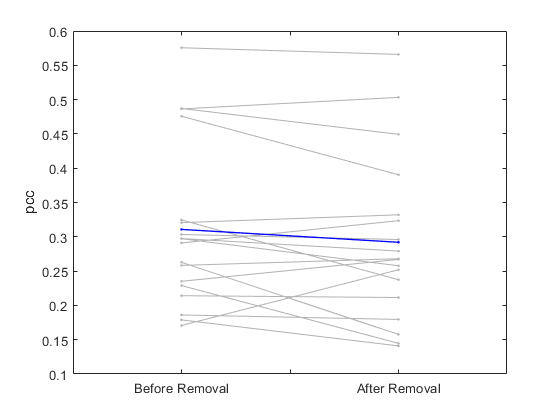

N=18;
pcc=zeros(N,2);
for p=1:N
    ca1=zscore(E{p}{1}.dFFCalciumTraces);ca2=zscore(E{p}{2}.dFFCalciumTraces);
    X=corrcoef(mean(ca1,2),mean(ca2,2));
    pcc(p,1)=X(1,2);
    ca1(:,remov{p,1})=[];ca2(:,remov{p,2})=[];
    X=corrcoef(mean(ca1,2),mean(ca2,2));
    pcc(p,2)=X(1,2);
end
p1=plot(pcc','.-k','Color',0.7*[1 1 1]);xlim([0.5 2.5]);xticklabels({[],'Before Removal',[],'After Removal',[]});
hold on 
p2=plot(mean(pcc),'.-b','LineWidth',1);ylabel('pcc')